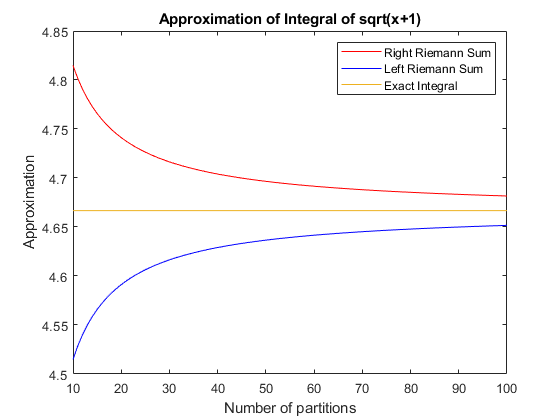

N = 10:100;
a = 0;
b = 3;

Ln = zeros(1, 91);
Rn = zeros(1, 91);

for n = 10:100
    elements = 1:n;
    elements = (sqrt(((elements - 1)*3/n) + 1)) * 3/n;
    S = sum(elements);
    Ln(n-9) = S;
    
    elements = 1:n;
    elements = (sqrt((elements*3/n)+1)) * 3/n;
    S = sum(elements);
    Rn(n-9) = S;
end

exact_integral = (ones(1, 91)) * 14/3;

plot(N, Rn, 'r')
hold on
plot(N, Ln, 'b')
plot(N, exact_integral)
legend('Right Riemann Sum', 'Left Riemann Sum', 'Exact Integral')
title('Approximation of Integral of sqrt(x+1)')
xlabel("Number of partitions")
ylabel('Approximation')